# pose.mat

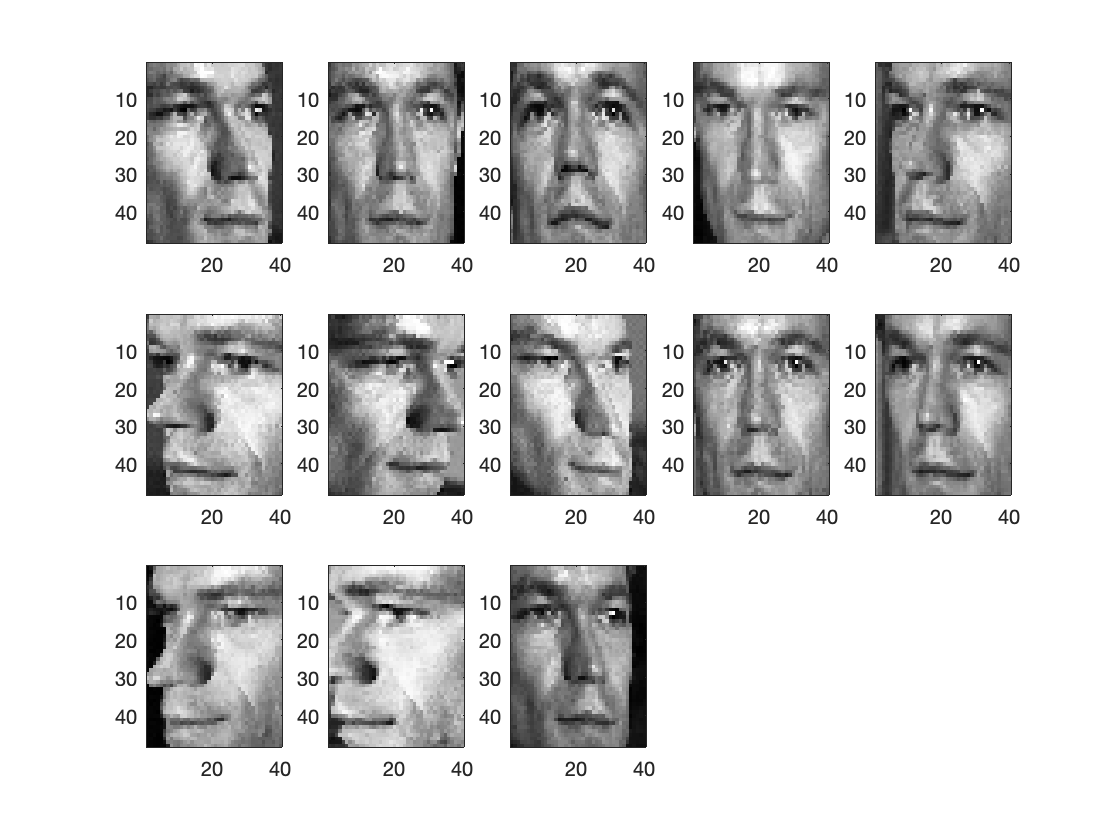

clear all
close all
data = load('pose.mat');
pose = data.pose;
figure; colormap gray
for j = 1 : 13
    subplot(3,5,j);
    imagesc(pose(:,:,j,5));
end

## Use PCA for preprocessing

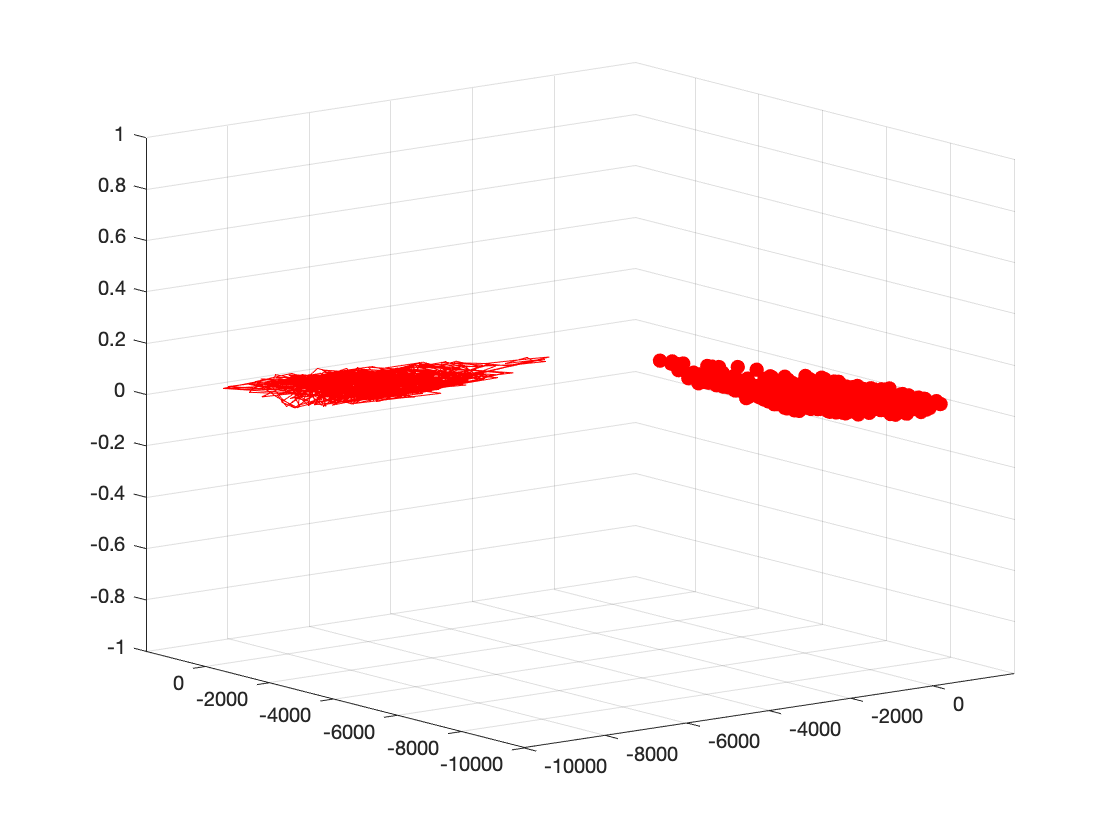

[d1,d2,n] = size(pose);
X1 = zeros(n,d1*d2); % data for neutral faces
X2 = zeros(n,d1*d2); % data for smiley face

for j = 1 : n
    aux = pose(:,:,j);
    X1(j,:) = aux(:)';
    aux = pose(:,:,j);
    X2(j,:) = aux(:)';
end
n1 = n;
n2 = n;
m1 = mean(X1,1); % column mean for X1
m2 = mean(X2,1); % column mean for X2

Xc1 = X1-ones(n1,1)*m1; % center X1
S1 = Xc1'*Xc1; % scatter matrix for X1

Xc2 = X2-ones(n2,1)*m2; % center X2
S2 = Xc2'*Xc2; % scatter matrix for X2

Sw = S1+S2; % compute matrix sw, within class scatter
Sb = (m1-m2)'*(m1-m2);
[W,lam0] = eig(Sb,Sw); % solve generalized eigenvalue problem
lam = diag(lam0);
[lam,isort] = sort(lam,'descend');

W = W(:,isort); % sort eigenvalues
w = W(:,1); % found eigenvector corresponds to the largest eigenvalue

X = [X1;X2];
D1 = 1:n1;
D2 = n1+1:n1+n2;

[U,Sig,V] = svd(X', 'econ');
nPCA = 5;
% project to nPCA-dimenionsal space
Y = X*U(:,1:nPCA);
figure;
hold on;
grid;
plot(Y(D1,1),Y(D1,2),Y(D1,3),Y(D1),'.','MarkerSize',20,'color','k');
plot(Y(D2,1),Y(D2,2),Y(D2,3),Y(D2),'.','MarkerSize',20,'color','r');

% Show in 4D
view(3);

## Use MDA for preprocessing

[d1,d2,n] = size(face_neutral);
X1 = zeros(n,d1*d2); % data for neutral faces
X2 = zeros(n,d1*d2); % data for smiley face

for j = 1 : n
    aux = face_neutral(:,:,j);
    X1(j,:) = aux(:)';
    aux = face_exp(:,:,j);
    X2(j,:) = aux(:)';
end

n1 = n;
n2 = n;
m1 = mean(X1,1); % column mean for X1
m2 = mean(X2,1); % column mean for X2

Xc1 = X1-ones(n1,1)*m1; % center X1
S1 = Xc1'*Xc1; % scatter matrix for X1

Xc2 = X2-ones(n2,1)*m2; % center X2
S2 = Xc2'*Xc2; % scatter matrix for X2

Sw = S1+S2; % compute matrix sw, within class scatter
Sb = (m1-m2)'*(m1-m2);
[W,lam0] = eig(Sb,Sw); % solve generalized eigenvalue problem
lam = diag(lam0);
[lam,isort] = sort(lam,'descend');

W = W(:,isort); % sort eigenvalues
w = W(:,1); % found eigenvector corresponds to the largest eigenvalue

X = [X1;X2];
D1 = 1:n1;
D2 = n1+1:n1+n2;

[U,Sig,V] = svd(X', 'econ');
nPCA = 15;
% project to nPCA-dimenionsal space
Y = X*U(:,1:nPCA);
figure;
hold on;
grid;
plot3(Y(D1,1),Y(D1,2),Y(D1,3),'.','MarkerSize',20,'color','k');
plot3(Y(D2,1),Y(D2,2),Y(D2,3),'.','MarkerSize',20,'color','r');

% Show in 3D
view(3);
